%FFT
%Part-1.
clear;
clc;
close all;

%Values
a=2; b=5; L=128; n=0:L-1;
omega_1=pi/2; omega_2=pi/4;

%Given Signal.
x=a*sin(omega_1*n)+b*cos(omega_2*n);

%Generated Signal from x(n).
z=[abs(x(1:L/2)) -1*abs(x(L/2+1:L))];

%Performing DIT-FFT.
Z_omega=DITFFT(z);

%Calculating FFT using in-built function.
Z_omega_0=fft(z);

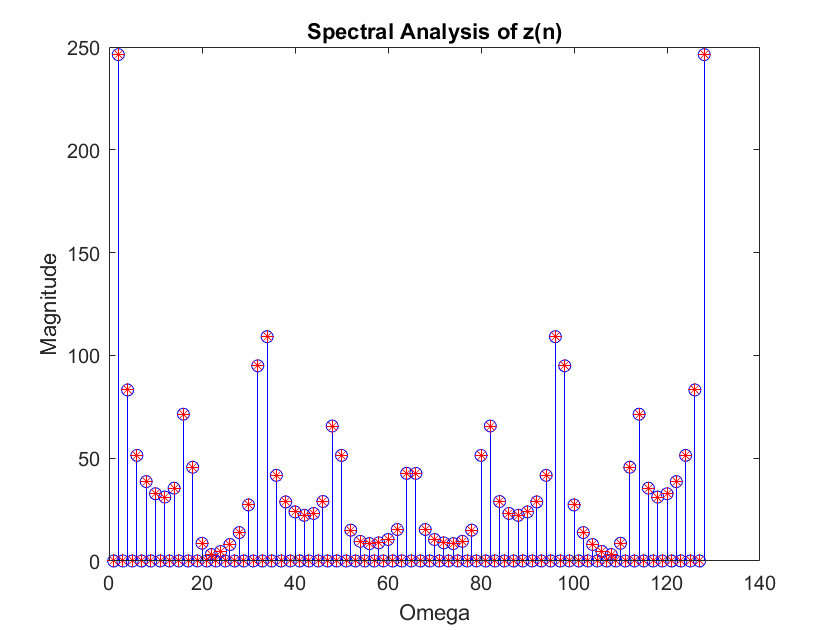

figure;
stem(abs(Z_omega),'b');
hold on;
plot(n+1,abs(Z_omega_0),'r*');
hold off;
title('Spectral Analysis of z(n)');
xlabel('Omega');
ylabel('Magnitude');

%Part-2.
clear;

%Values.
a=3; b=7; L=32; n=0:L-1;
omega_1=3*pi/2; omega_2=7*pi/4;

%Generating 5 random variances.
variance=randperm(L,6);

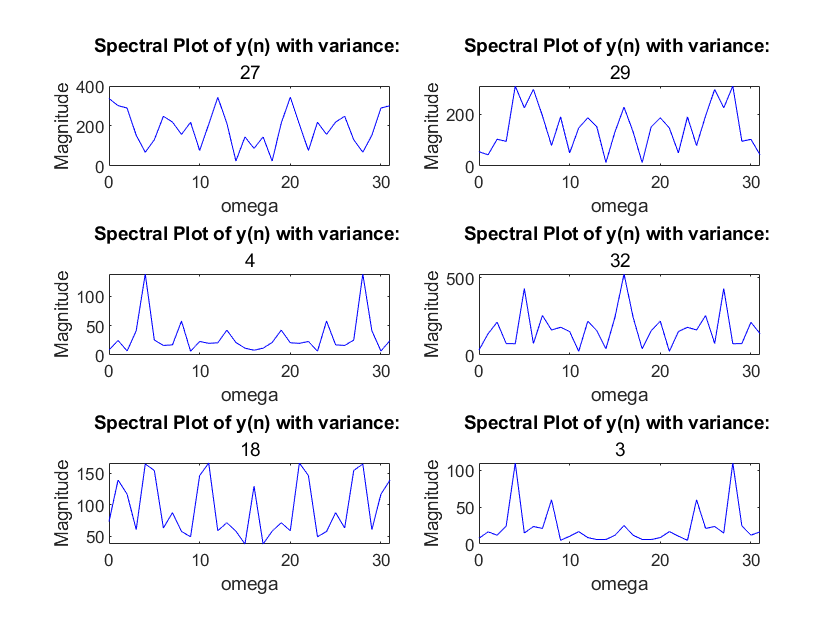

%Plotting the Graphs.
figure;
for i=1:6
    %Noise
    noise=0+randn(size(n)).*variance(i);
    %Given Signal.
    y=a*sin(omega_1*n)+b*cos(omega_2*n)+noise;
    Y_omega=DITFFT(y);
    
    subplot(3,2,i);
    plot(n,abs(Y_omega),'b');
    title('Spectral Plot of y(n) with variance: ',variance(i));
    xlabel('omega');
    ylabel('Magnitude');
end

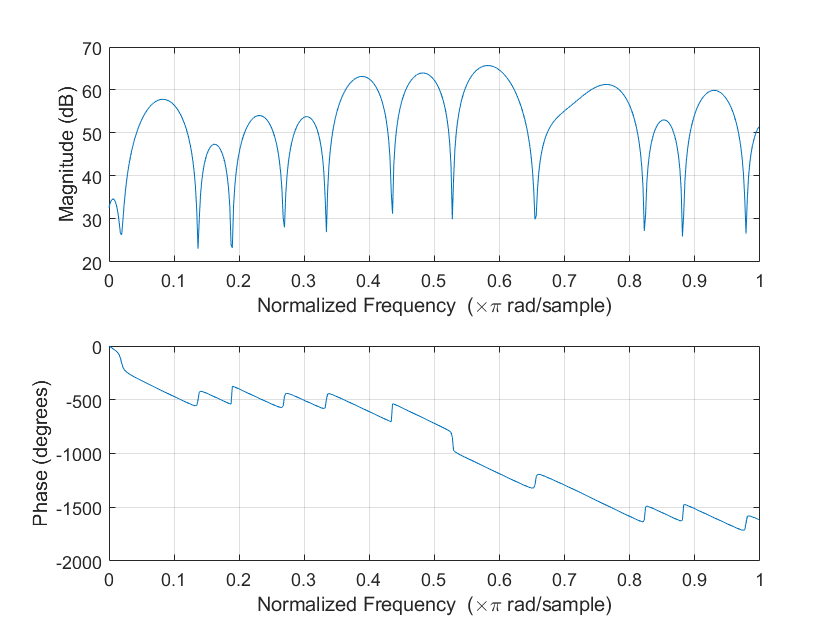

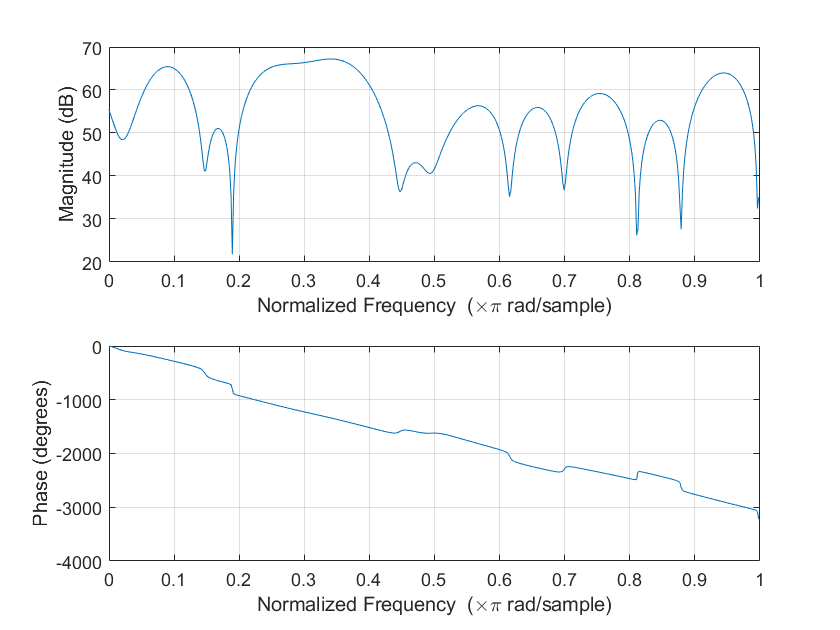

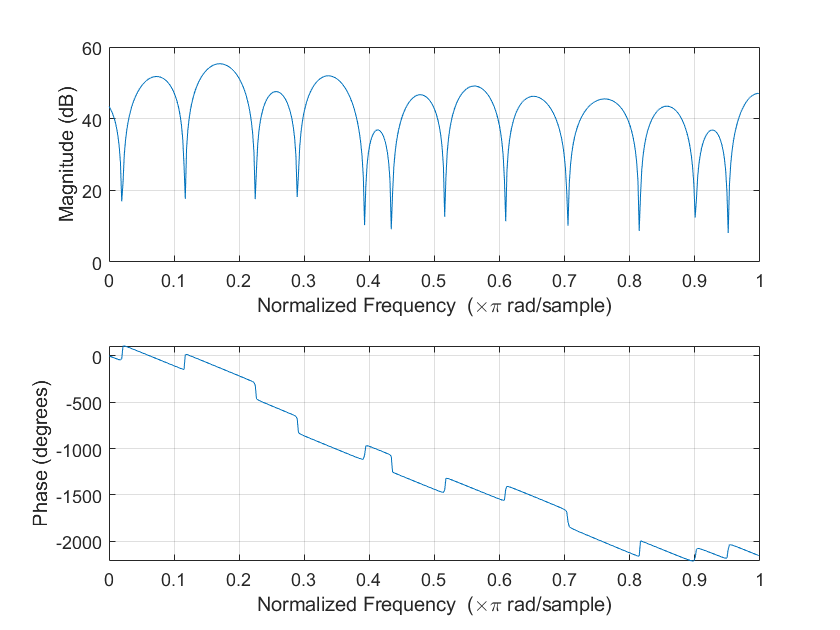

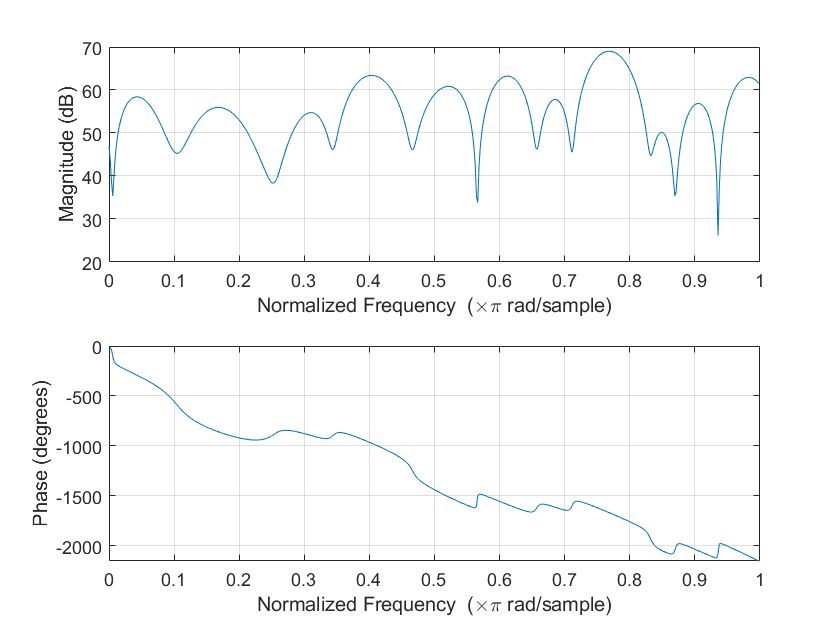

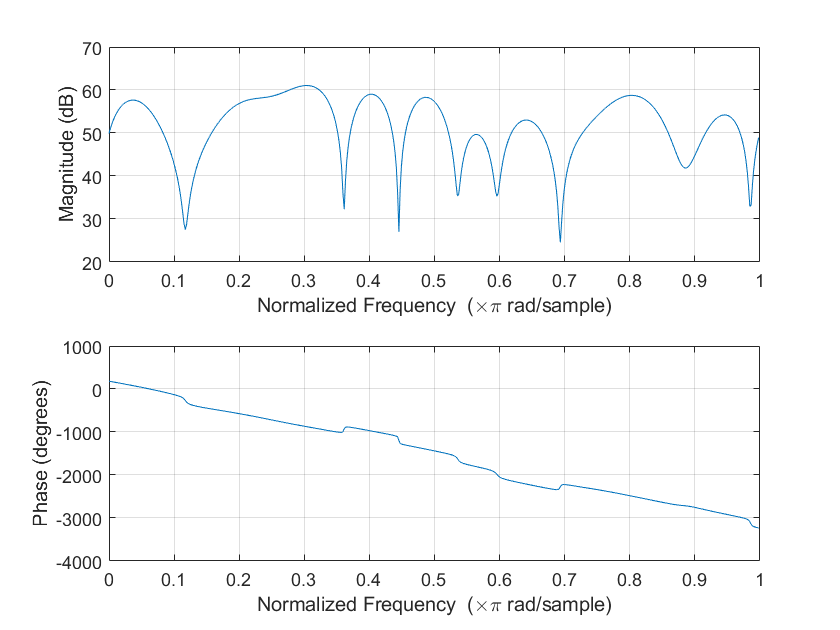

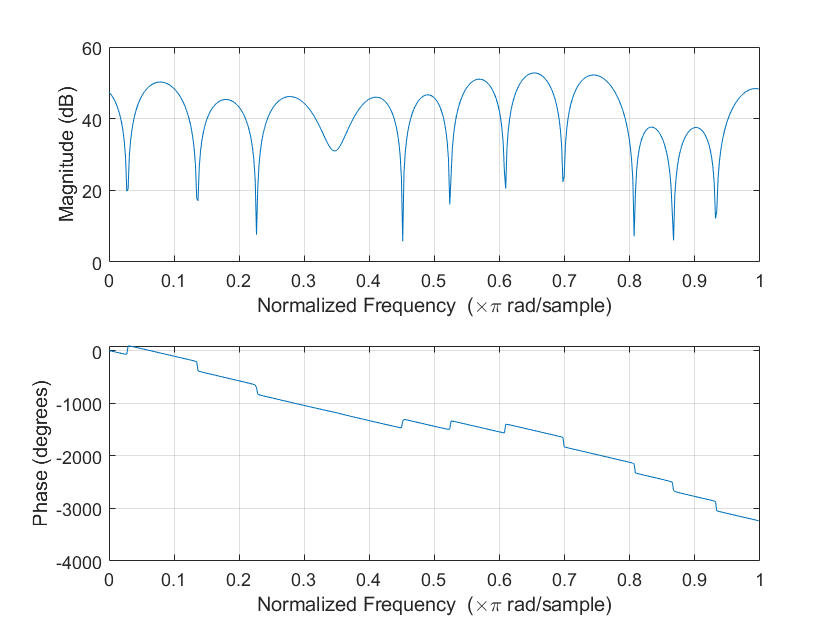


for i=1:6
    %Noise
    noise=0+randn(size(n)).*variance(i);
    %Given Signal.
    y=a*sin(omega_1*n)+b*cos(omega_2*n)+noise;
    
    Y_omega=DITFFT(y);
    figure;
    freqz(Y_omega);
end

%With the increase in noise power, the magnitude of the spectral lines
%keeps on rising.

%IIR Filters
%Question-2
clear;

%Parameters.
fs=48000;
Nyquist=fs/2;

Wp=6000/Nyquist; Ws=12000/Nyquist;
Rp=1; 
Rs=35;

%Calculating the Order and Cutoff Frequency.
[n,Wc] = buttord(Wp,Ws,Rp,Rs,'s');

%Calculating bk and ak.
[B,A]=butter(n,Wc,'s');

%Transfer Function in s-domain.
sos=zp2sos(B,A);
s=tf(B,A)

s =
 
                                            0.000139
  ---------------------------------------------------------------------------------------------
  s^7 + 1.264 s^6 + 0.7983 s^5 + 0.3244 s^4 + 0.09121 s^3 + 0.01775 s^2 + 0.002221 s + 0.000139
 
Continuous-time transfer function.



%Impulse Invariance.
[bz,az] = impinvar(B,A,fs);

%Bilinear Transformation.
[numd,denumd]=bilinear(B,A,fs);

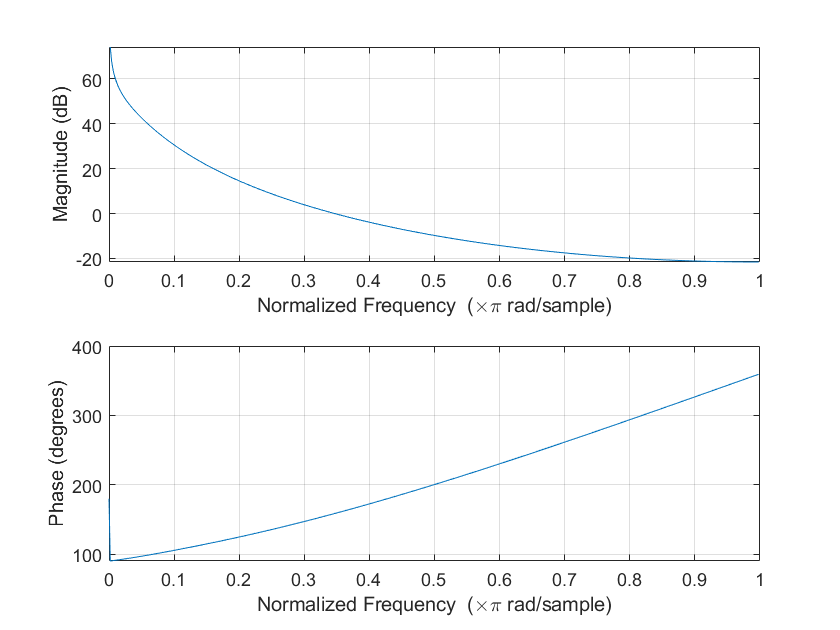

%Plotting the Frequency Responses.
%s-domain Transfer Function.
figure;
freqz(sos);

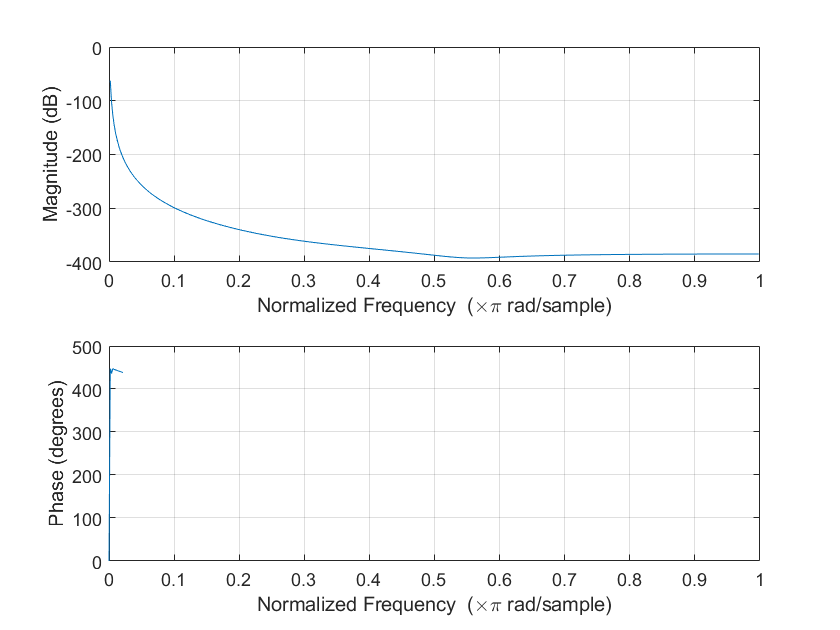


%Impulse Invariance.
figure;
freqz(bz,az);

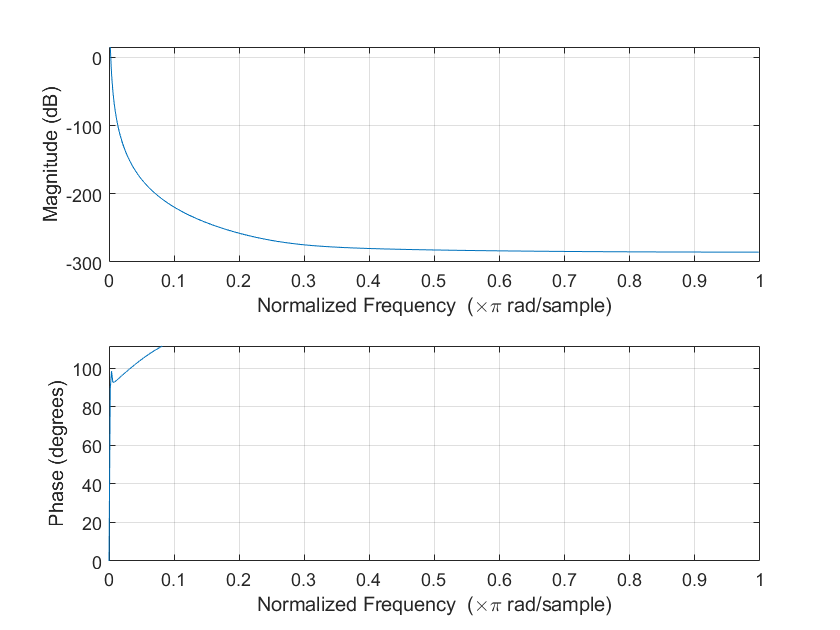


%Bilinear Transformation.
figure;
freqz(numd,denumd);

%FIR Filters.
%Question-3.
clear;

%Building a Low Pass Filter using Hamming Window.
%Parameters of the filter.

%Pass Frequency and Stop Frequency.
omega_p=pi/4; omega_s=pi/3;

%Parameters.
N=8;
epsilon=0.19;

%Critical Frequency.
omega_c=omega_p*(epsilon)^(-1/N);

%Window Length.
M=(8*pi)/(omega_s-omega_p);

%Generating a signal.
N=256;
n=0:N-1;
omega_0=pi/4;

%Signal.
x=sin(omega_0/2.*n)+2*cos(omega_0.*n)+3*sin(2*omega_0.*n);

%Hamming Window.
w_n=0.54-0.46*cos(2.*n*pi/M);

%Impulse Response of the filter.
h_n=w_n.*(omega_c/pi).*sinc(omega_c.*(n-(M/2))/pi);

%Filtered Output.
y=filter(h_n,1,x);

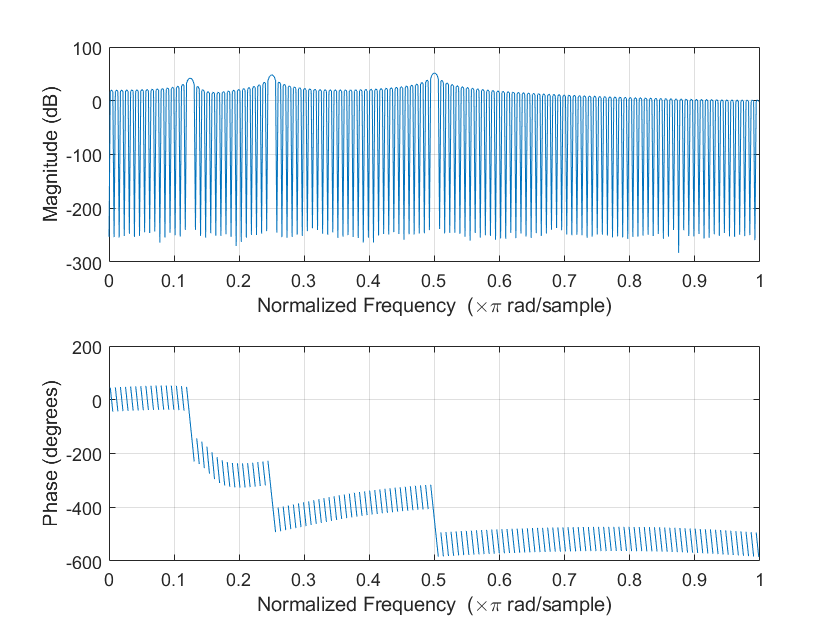

%Visualisation.
%Input Signal.
figure;
freqz(x);

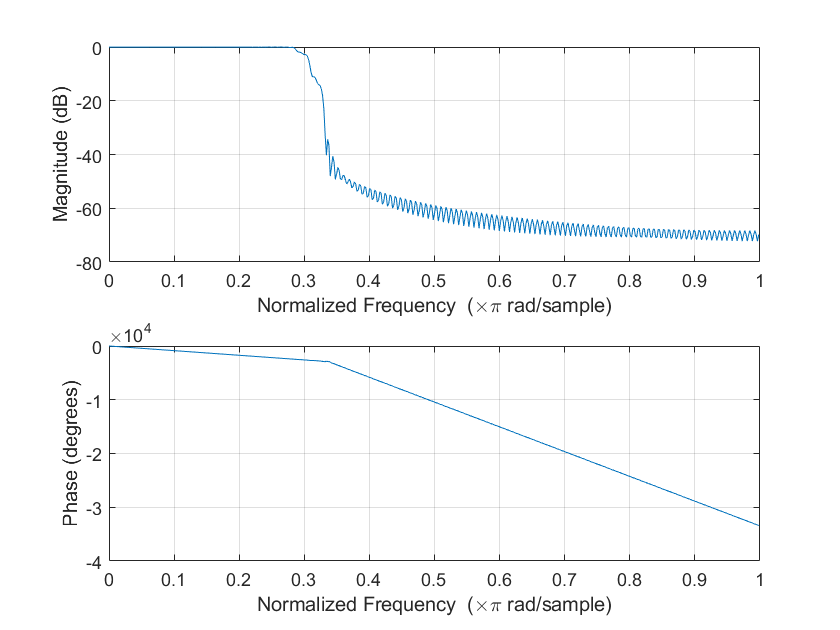


%Filter Impulse Response.
figure;
freqz(h_n);

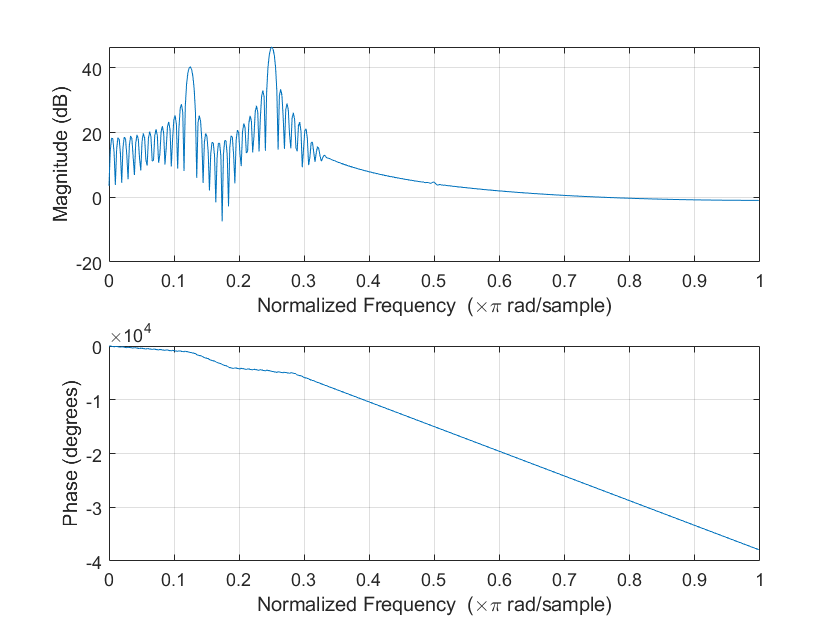


%Output Signal.
figure;
freqz(y);

%Building a Bandstop Filter using Hanning Window.
%The omega_0=pi/4.

%Bandstop filter of order=10
h=fir1(40,[0.10 0.40],'stop',hann(41));

%Filter Output.
y=filter(h,1,x);

%Visualisation.
%Input Signal.
figure;
freqz(x);

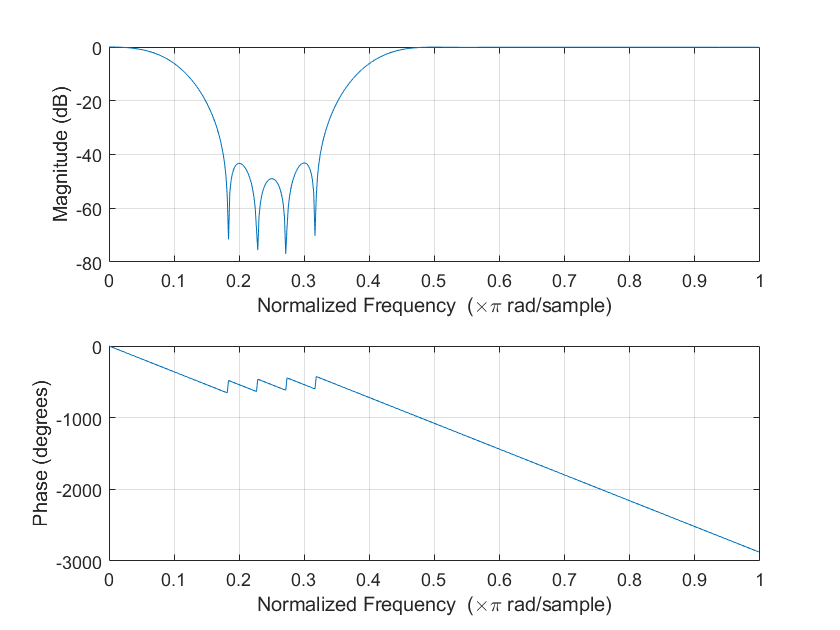


%Filter Impulse Response.
figure;
freqz(h);

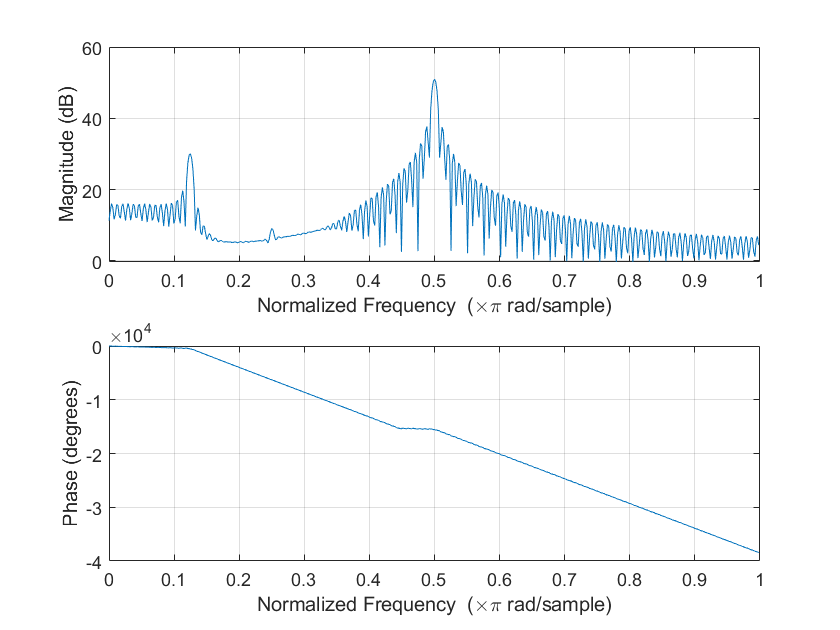


%Output Signal.
figure;
freqz(y);

%It is clearly visualized that the frequency components at omega=pi/4 is
%attenuated. The magnitude decresed from 45dB to 9dB using Hanning
%Window.

function a=DITFFT(x)
N=length(x);
if N>1
    N_2=N/2;
    x_even=DITFFT(x(1:2:N-1));
    x_odd=DITFFT(x(2:2:N));
    fiddle=exp(-1j*2*pi/N).^[0:N_2-1];
    a=[(x_even+x_odd.*fiddle) (x_even-x_odd.*fiddle)];
else
    a=x;
end
end